# 6주차 — 근궤적: 이득을 바꾸면 극점이 어디로 가는가

**제어시스템설계** · 충남대학교 자율운항시스템공학과

**참고자료 — 먼저 볼 것**

아래 다섯 과목은 **이 강의의 담당교수가 직접 한 강의**입니다. 기초부터 대학원 과정까지 이어지므로 부족한 곳부터 보면 됩니다. 이 강의에서 쓰는 기호와 유도는 모두 그 안에서 자세히 다룹니다.

**MATLAB 이나 Simulink 가 아직 익숙하지 않다면** 실습에 들어가기 전에 아래를 먼저 하십시오. 무료이고 각각 몇 시간이면 끝납니다.

오늘 두 주 동안 준비한 것이 하나로 합쳐집니다.

- **4주차** — 사양을 $s$ 평면의 영역으로 그렸다

- **5주차** — $K$ 를 바꾸면 극점이 움직인다는 것을 봤다

- **오늘** — 그 움직임을 제대로 그리고, 영역을 지나는 지점의 $K$ 를 읽는다

**그것이 곧 제어기 설계입니다.**

if isempty(which('plant_msd'))   % 경로가 아직 등록 안 되었으면 알아서 잡는다
    p_ = pwd;
    if ~isempty(mfilename('fullpath')), p_ = fileparts(mfilename('fullpath')); end
    for k_ = 1:4
        if isfile(fullfile(p_,'setup_path.m')), run(fullfile(p_,'setup_path.m')); break; end
        p_ = fileparts(p_);
    end
    clear p_ k_
end
clc; close all;
s = tf('s');

## 0-0. 오늘 돌려 볼 파일

강의노트를 읽다가 **직접 값을 바꿔 보고 싶을 때** 여는 파일들입니다. 모두 `W06_RootLocus_Basics` 폴더 안에 있습니다.

실행하는 법 — 파일을 열고 절 안에서 `Ctrl+Enter` 를 누르면 그 절만 돕니다. 전체는 `F5` 입니다. 처음 한 번은 `setup_path` 를 먼저 실행하십시오.

이 강의노트의 **그림은 전부** `make_figures.m` 이 만들어 `common/figures/` 에 넣어 둔 것입니다. 그림마다 어느 함수가 만들었는지 아래에 적어 두었습니다.

## 0. 오늘 한 장 요약

5주차에서 이득을 키우며 극점을 하나씩 찍어 봤습니다. 그 점들을 이으면 **길** 이 됩니다. 그 길이 **근궤적** 입니다.


$$K : 0 \rightarrow \infty \qquad \Rightarrow \qquad \text{폐루프 극점이 지나가는 길}$$


왜 유용한가

- 이득을 하나 고르는 일이 **길 위의 점 하나를 고르는 일**이 된다

- 4주차에서 배운 "사양 = $s$ 평면의 영역" 과 겹치면 **설계가 된다**

오늘의 계단

- **1절** 근궤적이 무엇이고, 그 뿌리인 **각도 조건과 크기 조건**

- **2절** `rlocus` 로 그리는 법과 주의

- **3~4절** 손으로 그리는 다섯 규칙 — 출발·도착점, **실축 구간**, 점근선, **이탈점**, **허수축 교차와 임계 이득**

- **5절** 오늘의 핵심. 극이나 영을 추가하면 길이 어떻게 휘는가

- **6~8절** `sgrid` 로 사양 영역을 겹치고 이득을 고르는 절차

- **9~10절** 설계가 실패하는 경우와 포화 문제

오늘 딱 하나만 기억한다면 이것입니다.

- **비례이득은 길 위에서 점을 옮길 뿐, 길 자체는 못 바꾼다**

그리고 오늘의 도구는 **손과 자**입니다. MATLAB 은 검산용입니다. 각도 조건 하나만 알면 나머지 규칙은 전부 거기서 따라 나옵니다.

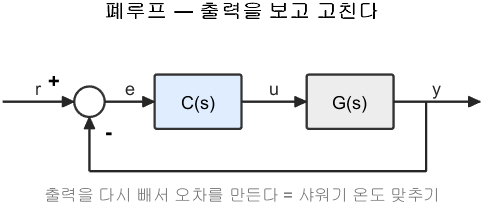

폐루프 — 출력을 보고 고친다

**그림 파일** `loop_closed.png` — `common/dg_loop.m` 의 `dg_loop` · 다시 만들려면 `make_figures('loop_closed')`

**만드는 곳** — `common/dg_loop.m` 을 `dg_loop('closed', ...)` 로 부릅니다

그림 해석

이 루프 모양은 학기 내내 바뀌지 않습니다. 바뀌는 것은 $C(s)$** 안에 무엇을 적는가**뿐입니다.

## 0-1. 가장 작은 예부터

이해를 돕기 위해 극점이 둘뿐인 것부터 봅니다.


$$G(s) = \frac{1}{(s+1)(s+3)}$$


이득을 키우며 극점을 직접 찍어 보겠습니다.

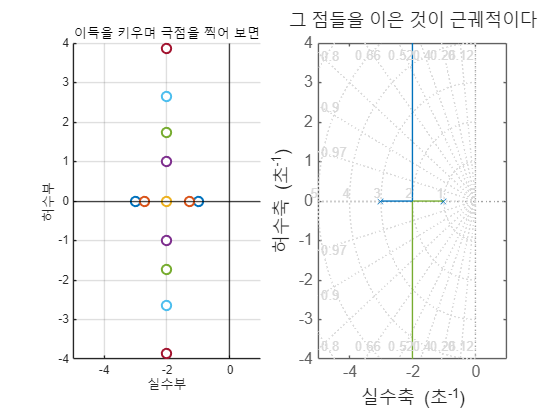

G0 = 1/((s+1)*(s+3));
figure;
tiledlayout(1,2,'TileSpacing','compact');
nexttile
hold on; grid on;
Kv = [0 0.5 1 2 4 8 16];
for K = Kv
    r = roots([1 4 3+K]);
    plot(real(r), imag(r), 'o', 'MarkerSize', 7, 'LineWidth', 1.5, ...
         'MarkerFaceColor', 'w');
end
xline(0,'k-'); yline(0,'k-');
xlim([-5 1]); ylim([-4 4]);
xlabel('실수부'); ylabel('허수부');
title('이득을 키우며 극점을 찍어 보면');
nexttile
rlocus(G0); grid on;
xlim([-5 1]); ylim([-4 4]);
title('그 점들을 이은 것이 근궤적이다');

왼쪽 그림의 점들이 오른쪽 선 위에 그대로 놓입니다. `rlocus` 는 그 점 찍기를 자동으로 해 주는 명령일 뿐입니다.

이 예에서 보이는 것

- 이득이 $0$ 이면 극점은 개루프 극점 $-1$, $-3$ 에 있다 (**출발점**)

- 이득을 키우면 둘이 서로 다가와 $-2$ 에서 만난다

- 더 키우면 위아래로 갈라져 **세로로** 올라간다

- 실수부가 $-2$ 에서 변하지 않으므로 **아무리 키워도 안정**하다

fprintf('=== 가장 작은 예 ===\n');

=== 가장 작은 예 ===


fprintf('     K    폐루프 극점\n');

     K    폐루프 극점


fprintf('  ------  --------------------------\n');

  ------  --------------------------


for K = [0 1 4 16]
    fprintf('  %6.1f  %s\n', K, mat2str(round(roots([1 4 3+K]).', 3)));
end

     0.0  [-3 -1]
     1.0  [-2 -2]
     4.0  [-2+1.732i -2-1.732i]
    16.0  [-2+3.873i -2-3.873i]


fprintf('  --> 실수부가 -2 로 고정되어 결코 우반면으로 못 갑니다\n\n');

  --> 실수부가 -2 로 고정되어 결코 우반면으로 못 갑니다



## 1. 근궤적이란

폐루프 특성방정식은 이것입니다.


$$1 + K L(s) = 0$$


여기서 $L(s)$ 는 개루프 전달함수에서 $K$ 를 뺀 나머지입니다. $K$ 를 $0$ 에서 무한대까지 바꾸면 이 방정식의 근이 움직이고, 그 자취를 **근궤적**이라 합니다.

5주차에서 `roots` 로 직접 만든 그 그림에 이름이 붙은 것입니다.

말로 하면 추상적이니, **점을 네 개만 찍어** 보겠습니다.

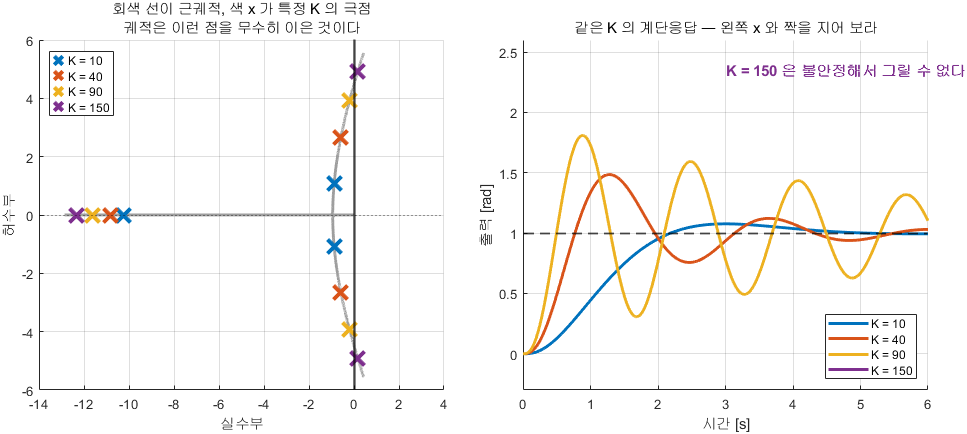

궤적은 특정 K 의 극점을 무수히 이은 것

**그림 파일** `w06_what_is.png` — `make_figures.m` 의 `fig_w06_what_is` · 다시 만들려면 `make_figures('w06_what_is')`

**만드는 곳** — `make_figures.m` 의 `fig_w06_what_is` **직접 바꿔 보려면** — `W06_01_rlocus_rules.m` 의 **1절**에서 `Ks` 목록을 바꿔 실행

그림 해석 — **왼쪽 **$\times$** 와 오른쪽 곡선을 색으로 짝지어 읽으십시오**

**왼쪽 그림 하나로 오른쪽 네 개를 전부 예측할 수 있습니다.** 이것이 근궤적을 쓰는 이유입니다.

## 1-1. 이 식은 어디서 나왔는가

$1 + KL(s) = 0$ 을 갑자기 받아들이지 말고 어디서 왔는지 확인합니다. 3주차에서 유도한 폐루프 전달함수에서 한 줄로 나옵니다.


$$T(s) = \frac{K\,G(s)}{1 + K\,G(s)H(s)}$$


**극점은 분모를 **$0$** 으로 만드는 **$s$ 였습니다 (2주차). 그러므로 폐루프 극점은 다음 식의 근입니다.


$$1 + K\,G(s)H(s) = 0$$


여기서 $L(s) = G(s)H(s)$ 로 묶은 것이 **개루프 전달함수**입니다. 센서가 이상적이어서 $H = 1$ 이면 $L = G$ 가 됩니다.

즉 근궤적은 새로운 이론이 아니라 5주차에서 `roots` 로 하던 일에 **이름을 붙인 것**입니다. 다만 5주차에서는 $K$ 를 하나씩 넣어 근을 구했고, 오늘은 그 근들이 그리는 **선 전체의 성질**을 봅니다.

확인해 봅니다. 두 방법이 같은 답을 주어야 합니다.

G1 = 1/((s+1)*(s+3));
Ktest = 5;
fprintf('=== 같은 답인지 확인 ===\n');

=== 같은 답인지 확인 ===


fprintf('feedback 으로 만든 폐루프 극점 : %s\n', ...
        mat2str(round(pole(feedback(Ktest*G1, 1)).', 4)));

feedback 으로 만든 폐루프 극점 : [-2+2i -2-2i]


fprintf('특성방정식 1+KL=0 의 근        : %s\n', ...
        mat2str(round(roots([1 4 3+Ktest]).', 4)));

특성방정식 1+KL=0 의 근        : [-2+2i -2-2i]


## 1-2. 어떤 점이 궤적 위에 있는지 확인하는 법 — 각도 조건

**여기가 근궤적의 뿌리입니다.** 이 절만 이해하면 뒤의 규칙은 전부 따라 나옵니다.

특성방정식을 $L$ 에 대해 풀면 이렇습니다.


$$1 + K L(s) = 0 \quad\Rightarrow\quad L(s) = -\frac{1}{K}$$


$K$ 는 **양의 실수**입니다. 그러므로 $-1/K$ 도 **음의 실수**입니다. 어떤 복소수가 음의 실수가 되려면 두 가지가 동시에 성립해야 합니다.

순서가 중요합니다. **먼저 각도로 걸러 내고, 통과한 점에 대해서만 크기로 **$K$** 를 구합니다.**

각도와 크기를 실제로 세는 법은 그림으로 보면 간단합니다. $L(s)$ 를 인수로 쓰면


$$L(s) = \frac{(s+z_1)(s+z_2)\cdots}{(s+p_1)(s+p_2)\cdots}$$


이고, 각 인수 $(s + p_i)$ 는 **극점 **$-p_i$** 에서 시험점 **$s$** 로 향하는 벡터**입니다. 곱은 각을 더하고 나눗셈은 각을 빼므로


$$\angle L(s) = \sum(\text{영점에서 온 각}) - \sum(\text{극점에서 온 각})$$



$$K = \frac{1}{\left| L(s) \right|} = \frac{\prod(\text{극점까지의 거리})}{\prod(\text{영점까지의 거리})}$$


**자를 대고 재면 되는 일**입니다. 그림에서 확인합니다.

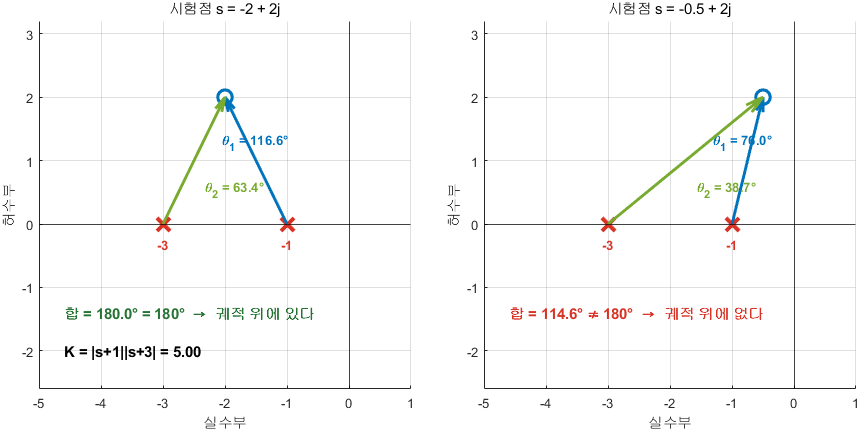

시험점에서 각을 더해 180도인지 본다

**그림 파일** `w06_angle_cond.png` — `make_figures.m` 의 `fig_w06_angle_cond` · 다시 만들려면 `make_figures('w06_angle_cond')`

**만드는 곳** — `make_figures.m` 의 `fig_w06_angle_cond` **직접 확인해 보려면** — 아래 코드에서 `s_test` 를 바꿔 가며 실행

그림 해석

각도 조건이 통과한 점에서 크기 조건으로 구한 $K=5$ 가 정말 맞는지 폐루프 극점으로 확인합니다.

s_test = -2 + 2i;
th1 = rad2deg(angle(s_test - (-1)));
th2 = rad2deg(angle(s_test - (-3)));
K_from_mag = abs(s_test + 1) * abs(s_test + 3);

fprintf('=== 각도 조건과 크기 조건 ===\n');

=== 각도 조건과 크기 조건 ===


fprintf('시험점 s = %s\n', num2str(s_test));

시험점 s = -2+2i


fprintf('  극점 -1 에서 온 각 : %.2f 도\n', th1);

  극점 -1 에서 온 각 : 116.57 도


fprintf('  극점 -3 에서 온 각 : %.2f 도\n', th2);

  극점 -3 에서 온 각 : 63.43 도


fprintf('  합                : %.2f 도  -> 180 도이면 궤적 위\n', th1 + th2);

  합                : 180.00 도  -> 180 도이면 궤적 위


fprintf('  크기 조건이 준 K   : %.4f\n', K_from_mag);

  크기 조건이 준 K   : 5.0000


fprintf('  그 K 의 폐루프 극점 : %s\n', ...
        mat2str(round(roots([1 4 3+K_from_mag]).', 4)));

  그 K 의 폐루프 극점 : [-2+2i -2-2i]


fprintf('  --> 시험점과 같으면 성공입니다.\n\n');

  --> 시험점과 같으면 성공입니다.



## 2. `rlocus` — 근궤적 그리기

- **하는 일** — $1 + KL(s) = 0$ 의 근을 $K=0$ 부터 무한대까지 추적해 그린다

- **입력** — 개루프 전달함수 $L$. $K$** 는 빼고** 넣는다

- **출력** — 받지 않으면 그림. `[r,k] = rlocus(L)` 로 받으면 근과 이득

주의 세 가지

- `rlocus(5*G)` 처럼 $K$ 를 곱해 넣지 말 것. 모양은 같지만 **이득 눈금이 어긋난다**

- $L$ 은 **개루프**다. `feedback` 을 쓰지 말고 $G$ 를 그대로 넣을 것

- 반환되는 이득 벡터의 마지막은 `Inf` 다. 계산할 때 걸러 낼 것

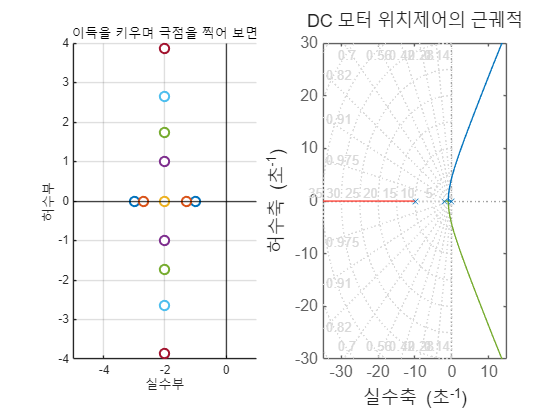

[Gp, ~] = plant_dcmotor('position');
rlocus(Gp); grid on
title('DC 모터 위치제어의 근궤적')

## 2-1. 중요한 주의 — `rlocus` 의 이득 눈금은 성기다

`rlocus` 는 **그림을 예쁘게 그리는 것**이 목적이라 이득을 촘촘히 훑지 않습니다. 실제로 $50$ 개 남짓만 계산합니다.

그래서 "궤적이 허수축을 넘는 정확한 이득" 을 `rlocus` 데이터에서 바로 읽으면 틀립니다.

- `rlocus` 눈금으로 읽은 값 — $K = 131.8$ (부정확)

- 촘촘히 훑어 구한 값 — $K = 120.14$ (정확)

- 5주차에서 손으로 구한 값 — $K = 120.12$

**그림은 rlocus 로 보고, 숫자는 따로 계산하십시오.** 5주차에서 배운 `roots` 반복이 그 방법입니다.

## 2-2. 또 하나의 주의 — `legend` 를 부르지 말 것

`rlocus` 로 그린 그림 위에 `legend` 를 부르면 R2024b 에서 **오류가 납니다.** Control System Toolbox 의 차트 객체가 범례를 자체 관리하기 때문입니다.

설명이 필요하면 `title` 이나 `text` 를 쓰십시오.

## 3. 궤적은 어디서 출발해 어디로 가는가

규칙은 식에서 바로 나옵니다. 외울 것이 없습니다.


$$1 + KL(s) = 0 \;\Longrightarrow\; L(s) = -\frac{1}{K}$$


- $K \to 0$ 이면 $L(s) \to \infty$ — 즉 $L$ 의 **극점**

- $K \to \infty$ 이면 $L(s) \to 0$ — 즉 $L$ 의 **영점**

따라서

- **규칙 1** — 궤적은 개루프 극점에서 **출발**한다

- **규칙 2** — 궤적은 개루프 영점에서 **끝난다**

- 영점이 부족하면 남는 가지는 **무한대로** 뻗어 나간다

영점이 있을 때와 없을 때를 나란히 놓으면 규칙 2 가 바로 보입니다.

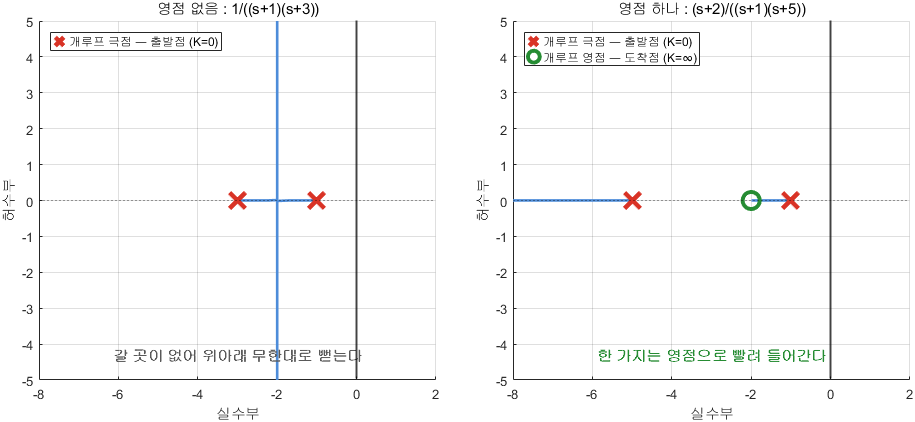

영점이 있으면 그리로 빨려 들어간다

**그림 파일** `w06_start_end.png` — `make_figures.m` 의 `fig_w06_start_end` · 다시 만들려면 `make_figures('w06_start_end')`

**만드는 곳** — `make_figures.m` 의 `fig_w06_start_end` **직접 바꿔 보려면** — `W06_01_rlocus_rules.m` 의 **2절**에서 영점 위치를 $-2$ 대신 $-0.5$ 나 $-4$ 로 옮겨 실행

그림 해석

오른쪽 그림이 7주차 PD 제어의 원리입니다. 영점을 하나 놓아 궤적을 실축 쪽으로 눌러 앉히는 것입니다.

## 3-1. 실축 위의 궤적 — 손작도에서 가장 먼저 하는 일

근궤적을 손으로 그릴 때 **제일 먼저 칠하는 것이 실축**입니다. 규칙은 한 줄이고, 1-2절의 각도 조건에서 바로 나옵니다.

**실축 위의 어떤 점에서, 그 점의 오른쪽에 있는 극점과 영점의 개수를 세십시오. 홀수이면 그 점은 궤적 위에 있고, 짝수(0 포함)이면 아닙니다.**

왜 그런지 보겠습니다. 실축 위의 시험점 $\sigma$ 를 잡으면

- $\sigma$ 의 **오른쪽**에 있는 실수 극·영 $\to$ 그 벡터는 왼쪽을 향하므로 각이 $180^\circ$

- $\sigma$ 의 **왼쪽**에 있는 실수 극·영 $\to$ 벡터가 오른쪽을 향하므로 각이 $0^\circ$

- **복소수 극·영** $\to$ 반드시 켤레쌍으로 있으므로 위아래 각이 상쇄되어 합이 $0^\circ$

그러므로 각의 총합은 (오른쪽 개수) $\times\,180^\circ$ 이고, 이것이 $180^\circ$ 의 **홀수배**가 되려면 오른쪽 개수가 홀수여야 합니다.

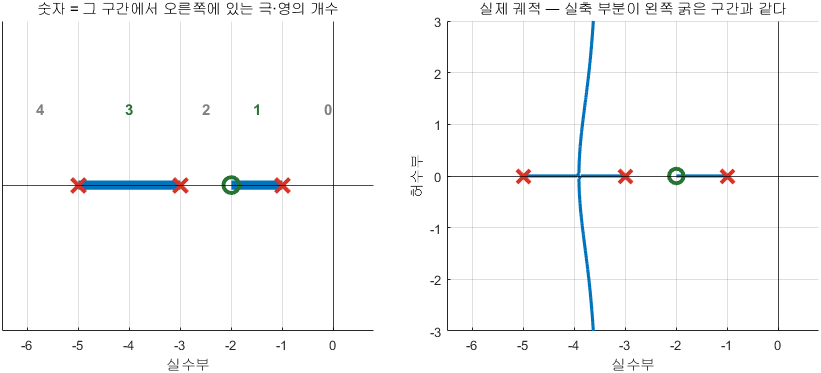

오른쪽 개수가 홀수인 구간만 궤적이다

**그림 파일** `w06_real_axis.png` — `make_figures.m` 의 `fig_w06_real_axis` · 다시 만들려면 `make_figures('w06_real_axis')`

**만드는 곳** — `make_figures.m` 의 `fig_w06_real_axis` **직접 확인해 보려면** — 아래 코드에서 극점과 영점 목록을 바꿔 실행

그림 해석

아래 코드는 이 세기를 그대로 옮긴 것입니다.

pz_all = [-1 -3 -5 -2];              % 극점 셋 + 영점 하나
edges  = sort(pz_all);
fprintf('=== 실축 규칙 손으로 세기 ===\n');

=== 실축 규칙 손으로 세기 ===


fprintf('  %-16s %-8s %s\n', '구간', '오른쪽 개수', '궤적인가');

  구간               오른쪽 개수   궤적인가


for i = 1:numel(edges)-1
    mid = (edges(i) + edges(i+1))/2;
    cnt = sum(pz_all > mid);
    fprintf('  %-16s %-8d %s\n', ...
        sprintf('%.0f ~ %.0f', edges(i), edges(i+1)), cnt, ...
        string(mod(cnt,2)==1));
end

  -5 ~ -3          3        true
  -3 ~ -2          2        false
  -2 ~ -1          1        true


fprintf('  %-16s %-8d %s\n', '-1 ~ 0', sum(pz_all > -0.5), ...
        string(mod(sum(pz_all > -0.5),2)==1));

  -1 ~ 0           0        false


fprintf('\n');

## 4. 가지 개수와 점근선

- **규칙 3** — 가지 개수 $=$ 개루프 극점 개수

- **규칙 4** — 무한대로 가는 가지 개수 $= n - m$ (극점 수 $-$ 영점 수)

- **규칙 5** — 점근선 각도


$$\theta = \frac{(2q+1)\cdot 180^\circ}{n-m}, \qquad q = 0,1,2,\ldots$$


- **규칙 6** — 점근선이 실축과 만나는 점


$$\sigma = \frac{\sum(\text{극점}) - \sum(\text{영점})}{n-m}$$


이 두 공식도 **외울 것이 아니라 1-2절의 각도 조건에서 나옵니다.** 다음 절에서 유도합니다.

## 4-0. 점근선 각도는 각도 조건을 멀리서 본 것이다

궤적이 무한대로 뻗어 나갈 때, 즉 $|s|$ 가 아주 클 때를 생각합니다.

**아주 멀리서 보면 극점과 영점이 전부 한 점(원점)에 뭉쳐 보입니다.** 지구에서 보면 서울과 부산이 다른 곳이지만 달에서 보면 한 점인 것과 같습니다.

그러면 개루프는 이렇게 보입니다.


$$L(s) = \frac{(s-z_1)\cdots(s-z_m)}{(s-p_1)\cdots(s-p_n)} \;\approx\; \frac{s^m}{s^n} = \frac{1}{s^{\,n-m}} \qquad (|s| \gg 1)$$


이제 **1-2절의 각도 조건**을 이 식에 그대로 씁니다. $s = |s|\,e^{j\theta}$ 라 하면 $\frac{1}{s^{n-m}}$ 의 각은 $-(n-m)\theta$ 이므로


$$\angle L(s) = -(n-m)\,\theta = \pm 180^\circ (2q+1)$$


양변을 $-(n-m)$ 으로 나누면 **규칙 5 가 그대로 나옵니다.**


$$\theta = \frac{(2q+1)\cdot 180^\circ}{n-m}$$


$q$ 에 $0, 1, 2, \ldots$ 를 넣으면 서로 다른 각이 $n-m$ 개 나오고, 그 개수가 곧 **무한대로 가는 가지의 개수**입니다 (규칙 4).

$n-m$** 이 클수록 각이 작아져 오른쪽으로 눕습니다.** 그래서 불안정해지기 쉽습니다.

## 4-0-1. 점근선 중심은 한 항 더 남긴 것이다

위에서는 $s^m/s^n$ 만 남기고 나머지를 다 버렸습니다. **한 항만 더 남기면 점근선이 실축과 만나는 자리까지 나옵니다.**

다항식을 전개하면 둘째 항의 계수가 근의 합입니다 (근과 계수의 관계).


$$(s-p_1)\cdots(s-p_n) = s^n - \left(\sum p_j\right)s^{n-1} + \cdots$$


분자도 같은 꼴이므로


$$L(s) \approx \frac{s^m - \left(\sum z_i\right)s^{m-1}} {s^n - \left(\sum p_j\right)s^{n-1}} = \frac{1}{s^{\,n-m}}\cdot \frac{1 - \left(\sum z_i\right)/s}{1 - \left(\sum p_j\right)/s}$$


$1/s$ 가 아주 작으므로 $\frac{1}{1-x} \approx 1+x$ 를 쓰면


$$L(s) \approx \frac{1}{s^{\,n-m}} \left(1 + \frac{\sum p_j - \sum z_i}{s}\right)$$


한편 점근선이 $s = \sigma$ 를 중심으로 뻗는다면 그 모양은 이렇습니다.


$$\frac{1}{(s-\sigma)^{\,n-m}} = \frac{1}{s^{\,n-m}}\left(1 - \frac{\sigma}{s}\right)^{-(n-m)} \approx \frac{1}{s^{\,n-m}}\left(1 + \frac{(n-m)\,\sigma}{s}\right)$$


**두 식의 **$1/s$** 계수를 맞추면** 규칙 6 이 나옵니다.


$$(n-m)\,\sigma = \sum p_j - \sum z_i \qquad\Rightarrow\qquad \sigma = \frac{\sum(\text{극점}) - \sum(\text{영점})}{n-m}$$


**읽는 법** — 점근선의 중심은 극점과 영점의 **무게중심** 같은 것입니다. 극점이 왼쪽에 많을수록 중심이 왼쪽으로 가고, 영점을 왼쪽에 놓으면 (빼기이므로) 중심이 오른쪽으로 밀립니다.

아래에서 손계산과 MATLAB 을 대조합니다.

La = 1/(s*(s+1)*(s+3));
pa = pole(La);  za = zero(La);
nma = numel(pa) - numel(za);
sig_hand = (sum(pa) - sum(za))/nma;
th_hand  = (2*(0:nma-1)+1)*180/nma;
fprintf('=== 점근선 손계산 ===\n');

=== 점근선 손계산 ===


fprintf('  극점 %s,  영점 %s\n', mat2str(round(pa.',3)), mat2str(za.'));

  극점 [0 -3 -1],  영점 zeros(1,0)


fprintf('  n-m = %d\n', nma);

  n-m = 3


fprintf('  중심 sigma = (%.3f - 0) / %d = %.4f\n', sum(pa), nma, sig_hand);

  중심 sigma = (-4.000 - 0) / 3 = -1.3333


fprintf('  각도 = (2q+1)*180/%d = %s 도\n', nma, mat2str(th_hand));

  각도 = (2q+1)*180/3 = [60 180 300] 도


fprintf('  --> 4-1절 그림의 빨간 점선과 대조해 보십시오.\n\n');

  --> 4-1절 그림의 빨간 점선과 대조해 보십시오.



%
% 정리하면 이렇습니다.
%
% **$n-m$ 이 클수록 궤적이 오른쪽으로 휘어 불안정해지기 쉽다**

## 4-1. 점근선을 눈으로 확인하기

말로만 하면 안 와닿습니다. 궤적 위에 점근선을 **직접 그려서** 겹쳐 봅니다. 빨간 점선이 공식으로 구한 점근선이고, 파란 곡선이 실제 궤적입니다.

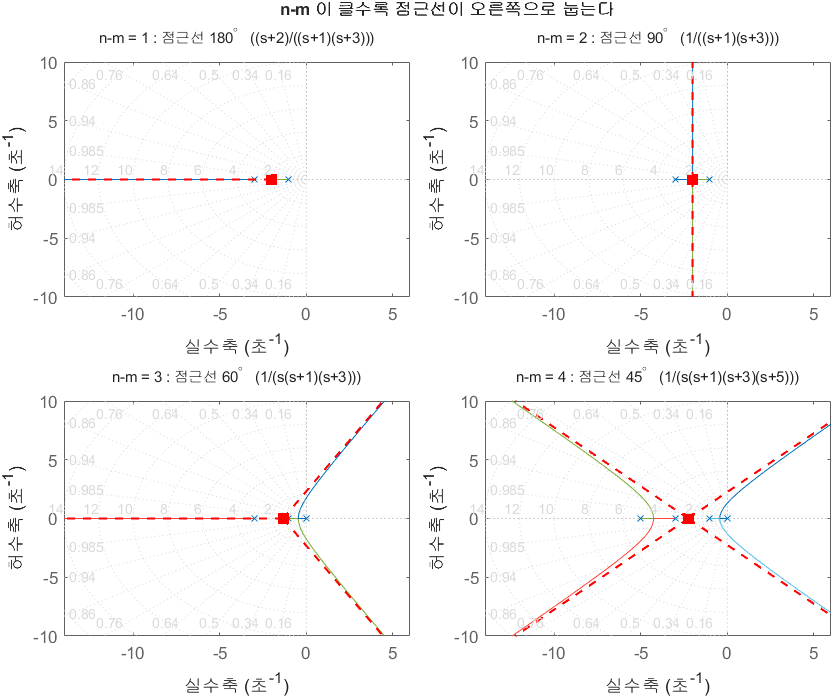

n-m 이 클수록 점근선이 오른쪽으로 눕는다

**그림 파일** `w06_asymptote.png` — `make_figures.m` 의 `fig_asymptote` · 다시 만들려면 `make_figures('w06_asymptote')`

**만드는 곳** — `make_figures.m` 의 `fig_asymptote` **직접 바꿔 보려면** — `W06_01_rlocus_rules.m` 의 **4절**에서 극점을 하나 더 붙여 보십시오. 점근선이 더 눕습니다

그림 해석 — **왼쪽 위에서 오른쪽 아래로 순서대로 보십시오**

외울 것은 **각도 **$= 180^\circ/(n-m)$ 하나입니다. $n-m$ 이 $1$ 이면 $180^\circ$(왼쪽), $2$ 면 $90^\circ$(수직), $3$ 이면 $60^\circ$, $4$ 면 $45^\circ$ — 점점 눕습니다.

그리고 이것이 **5주차에서 본 것과 같은 이야기**입니다. 적분기를 넣으면 극점이 하나 늘어 $n-m$ 이 커지고, 궤적이 더 눕습니다.

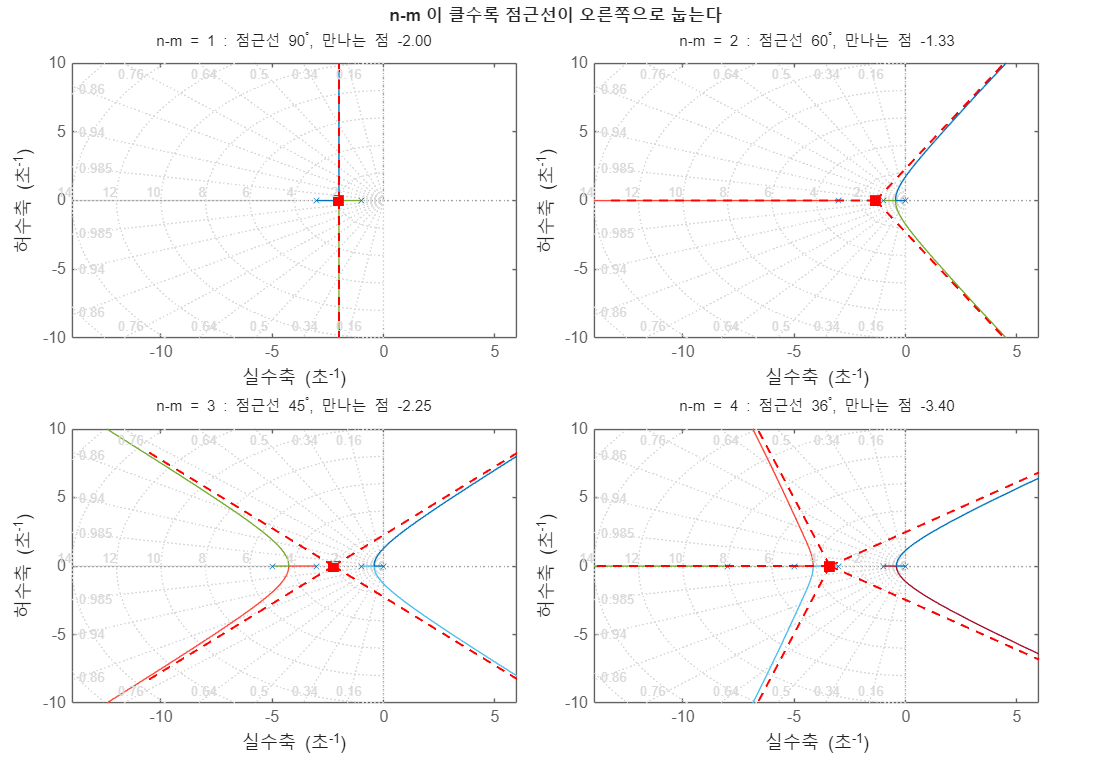

demo = { 'n-m = 1',  1/((s+1)*(s+3))
         'n-m = 2',  1/(s*(s+1)*(s+3))
         'n-m = 3',  1/(s*(s+1)*(s+3)*(s+5))
         'n-m = 4',  1/(s*(s+1)*(s+3)*(s+5)*(s+8)) };
figure('Position',[60 60 1100 760]);
tiledlayout(2,2,'TileSpacing','compact','Padding','compact');
for i = 1:4
    nexttile
    L = demo{i,2};
    pl = pole(L);  zr = zero(L);
    nn = numel(pl); mm = numel(zr);
    sg = real( (sum(pl) - sum(zr)) / (nn-mm) );
    th = (2*(0:(nn-mm-1))+1)*180/(nn-mm);
    rlocus(L); hold on;
    % 점근선 그리기
    Lr = 12;
    for q = 1:numel(th)
        plot(sg + [0 Lr]*cosd(th(q)), [0 Lr]*sind(th(q)), 'r--', 'LineWidth', 1.5);
    end
    plot(sg, 0, 'rs', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
    xlim([-14 6]); ylim([-10 10]); grid on;
    title(sprintf('%s : 점근선 %.0f^\\circ, 만나는 점 %.2f', ...
          demo{i,1}, th(1), sg), 'FontSize', 11);
end
sgtitle('n-m 이 클수록 점근선이 오른쪽으로 눕는다', 'FontSize', 13, 'FontWeight','bold');

그림에서 읽을 것

- $n-m = 1$ — 점근선이 $180^{\circ}$. 왼쪽으로만 간다. **절대 불안정해지지 않는다**

- $n-m = 2$ — $90^{\circ}$ 와 $270^{\circ}$. 수직으로 올라간다. 아슬아슬하다

- $n-m = 3$ — $60^{\circ}$. 오른쪽 위로 향한다. **언젠가 우반면으로 넘어간다**

- $n-m = 4$ — $45^{\circ}$. 더 빨리 넘어간다

**그래서 극점이 많은 시스템일수록 이득을 키우기 어렵습니다.**

반대로 **영점을 하나 더하면 **$n-m$** 이 하나 줄어듭니다.** 그것이 다음 절에서 볼 PD 제어의 원리입니다.

fprintf('=== 점근선 각도 확인 ===\n');

=== 점근선 각도 확인 ===


fprintf('  n-m   점근선 각도            불안정해질 수 있는가\n');

  n-m   점근선 각도            불안정해질 수 있는가


fprintf('  ---  --------------------  --------------------\n');

  ---  --------------------  --------------------


for i = 1:4
    L = demo{i,2};
    nm = numel(pole(L)) - numel(zero(L));
    th = (2*(0:(nm-1))+1)*180/nm;
    if nm >= 3, v = '예 (오른쪽으로 휜다)'; else, v = '아니오'; end
    fprintf('  %3d  ', nm);
    fprintf('%.0f ', th);
    fprintf('%s %s\n', repmat(' ', 1, max(0, 20-4*nm)), v);
end

    2  

90 270 

             아니오


    3  

60 180 300 

         예 (오른쪽으로 휜다)


    4  

45 135 225 315 

     예 (오른쪽으로 휜다)


    5  

36 108 180 252 324 

 예 (오른쪽으로 휜다)


fprintf('\n');

## 4-2. 이탈점 — 궤적은 어디서 실축을 떠나는가

0-1절의 그림에서 두 극점이 $-2$ 에서 만나 위아래로 갈라졌습니다. **왜 하필 **$-2$** 인가**에 답합니다.

특성방정식을 $K$ 에 대해 풀면 이렇습니다.


$$K = -\frac{1}{L(s)}$$


이 식을 **실축 위에서만** 그려 보십시오. $K(\sigma)$ 라는 보통의 함수가 됩니다. 실축 위의 두 가지가 서로 다가오다 만나는 자리는 **그 함수가 봉우리(최댓값)를 이루는 곳**입니다. 그보다 $K$ 를 더 키우면 실축 위에는 해가 없으므로 근이 복소수가 됩니다.

따라서 조건은 미분이 $0$ 인 곳입니다.


$$\frac{dK}{d\sigma} = 0$$


예제로 확인합니다. $L(s) = \frac{1}{(s+1)(s+3)}$ 이면


$$K(\sigma) = -(\sigma+1)(\sigma+3) = -(\sigma^2 + 4\sigma + 3)$$



$$\frac{dK}{d\sigma} = -(2\sigma + 4) = 0 \quad\Rightarrow\quad \sigma = -2$$


그리고 그때의 이득은 $K = -(-1)(1) = 1$ 입니다.

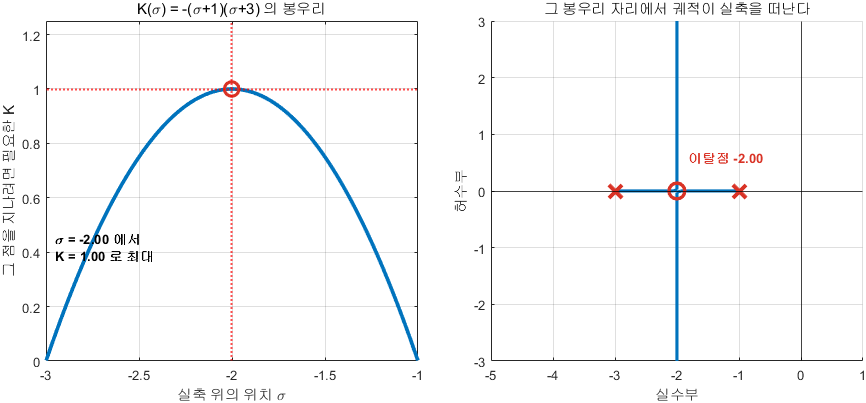

K가 최대가 되는 자리에서 궤적이 갈라진다

**그림 파일** `w06_breakaway.png` — `make_figures.m` 의 `fig_w06_breakaway` · 다시 만들려면 `make_figures('w06_breakaway')`

**만드는 곳** — `make_figures.m` 의 `fig_w06_breakaway` **직접 확인해 보려면** — 아래 코드에서 극점 위치를 $-1$, $-4$ 로 바꾸면 이탈점이 $-2.5$ 로 옮겨 갑니다

그림 해석

**이탈점은 중근이 생기는 자리**이기도 합니다. $K=1$ 에서 특성방정식은 $s^2+4s+4 = (s+2)^2$ 이 되어 근이 $-2$ 로 겹칩니다. 4주차의 말로 하면 **임계감쇠**($\zeta=1$)가 되는 이득입니다.

sig = linspace(-2.999, -1.001, 4001);
Ksig = -(sig+1).*(sig+3);
[Kbrk, ib] = max(Ksig);
fprintf('=== 이탈점 ===\n');

=== 이탈점 ===


fprintf('  수치로 찾은 이탈점 : sigma = %.4f, K = %.4f\n', sig(ib), Kbrk);

  수치로 찾은 이탈점 : sigma = -2.0000, K = 1.0000


fprintf('  손계산             : sigma = -2, K = 1\n');

  손계산             : sigma = -2, K = 1


r_brk = roots([1 4 3+Kbrk]);
fprintf('  그 K 의 폐루프 극점 : %s  (중근)\n', mat2str(round(r_brk.', 4)));

  그 K 의 폐루프 극점 : [-2 -2]  (중근)


fprintf('  그때의 감쇠비       : %.4f  (임계감쇠)\n\n', ...
        -real(r_brk(1))/abs(r_brk(1)));

  그때의 감쇠비       : 1.0000  (임계감쇠)



## 4-3. 허수축을 넘는 자리 — 임계 이득을 손으로 구한다

5주차에서 라우스 표로 구했던 **임계 이득**을 근궤적에서도 구할 수 있습니다. 방법이 더 간단합니다.

궤적이 허수축을 지나는 순간의 근은 $s = j\omega$ 입니다. 그러므로 특성방정식에 $s = j\omega$ 를 **대입해 버리면** 됩니다. 복소수 방정식 하나는 실수 방정식 두 개와 같으므로, 미지수 $K$ 와 $\omega$ 두 개를 정확히 구할 수 있습니다.

예제 $L(s) = \frac{1}{s(s+1)(s+3)}$ 로 해 봅니다. 특성방정식은


$$s^3 + 4s^2 + 3s + K = 0$$


$s = j\omega$ 를 넣으면 $s^2 = -\omega^2$, $s^3 = -j\omega^3$ 이므로


$$-j\omega^3 - 4\omega^2 + 3j\omega + K = 0$$


실수부와 허수부를 따로 $0$ 으로 둡니다.

$\omega = 0$ 도 해이지만 그것은 $K=0$ 인 원점 극점이므로 버립니다.

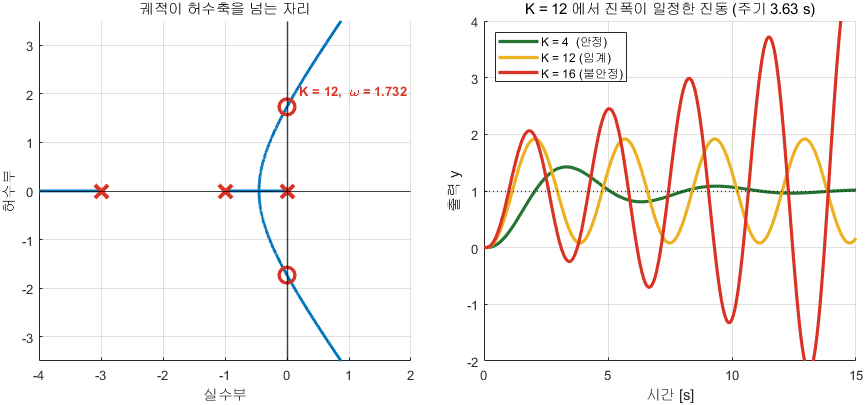

임계 이득에서는 진폭이 일정한 진동이 나온다

**그림 파일** `w06_jw_cross.png` — `make_figures.m` 의 `fig_w06_jw_cross` · 다시 만들려면 `make_figures('w06_jw_cross')`

**만드는 곳** — `make_figures.m` 의 `fig_w06_jw_cross` **직접 확인해 보려면** — 아래 코드에서 $K$ 값을 바꿔 가며 실행

그림 해석

노란 곡선의 주기를 자로 재면 $\omega$ 가 나옵니다. **손계산 · 근궤적 · 시간응답 세 가지가 같은 숫자를 가리키는 것**을 확인하십시오.

w_hand = sqrt(3);  K_hand = 4*w_hand^2;
L3 = 1/(s*(s+1)*(s+3));
fprintf('=== 허수축 교차 ===\n');

=== 허수축 교차 ===


fprintf('  손계산 : K = %.4f, omega = %.4f, 주기 = %.4f s\n', ...
        K_hand, w_hand, 2*pi/w_hand);

  손계산 : K = 12.0000, omega = 1.7321, 주기 = 3.6276 s


fprintf('  그 K 의 폐루프 극점 : %s\n', ...
        mat2str(round(pole(feedback(K_hand*L3,1)).', 4)));

  그 K 의 폐루프 극점 : [-4 0+1.7321i 0-1.7321i]


fprintf('  실수부가 0 이면 정확히 허수축 위입니다.\n');

  실수부가 0 이면 정확히 허수축 위입니다.


fprintf('  K = 11.5 일 때 극점 : %s (안정)\n', ...
        mat2str(round(pole(feedback(11.5*L3,1)).', 4)));

  K = 11.5 일 때 극점 : [-3.9734 -0.0133+1.7012i -0.0133-1.7012i] (안정)


fprintf('  K = 12.5 일 때 극점 : %s (불안정)\n\n', ...
        mat2str(round(pole(feedback(12.5*L3,1)).', 4)));

  K = 12.5 일 때 극점 : [-4.026 0.013+1.762i 0.013-1.762i] (불안정)



## 4-4. 손으로 그리는 다섯 단계 — 그리고 MATLAB 으로 검산

지금까지 나온 규칙을 실제로 그리는 순서로 세우면 다섯 단계입니다. **시험에서도 이 순서대로 하면 됩니다.**

그리고 마지막에 반드시 `rlocus` 로 검산합니다.

**손작도의 목적은 그림을 예쁘게 그리는 것이 아닙니다.** MATLAB 이 그려 준 그림이 **말이 되는지 판단할 눈**을 얻는 것입니다. 플랜트를 잘못 입력했거나 부호를 틀렸을 때, 손작도 감각이 없으면 이상한 그림을 그대로 믿게 됩니다.

아래 코드가 다섯 단계를 한 번에 확인합니다.

Lchk = 1/(s*(s+1)*(s+3));
pz   = [pole(Lchk).' zero(Lchk).'];
nmk  = numel(pole(Lchk)) - numel(zero(Lchk));

fprintf('=== 다섯 단계 검산 ===\n');

=== 다섯 단계 검산 ===


fprintf('1) 극점 %s,  영점 %s\n', ...
        mat2str(round(pole(Lchk).',3)), mat2str(zero(Lchk).'));

1) 극점 [0 -3 -1],  영점 zeros(1,0)


fprintf('2) 실축 궤적 구간 : -1 ~ 0 과 -3 아래쪽 (오른쪽 개수가 홀수인 곳)\n');

2) 실축 궤적 구간 : -1 ~ 0 과 -3 아래쪽 (오른쪽 개수가 홀수인 곳)


fprintf('3) n-m = %d  ->  점근선 각도 %s 도,  중심 %.4f\n', nmk, ...
        mat2str((2*(0:nmk-1)+1)*180/nmk), sum(pole(Lchk))/nmk);

3) n-m = 3  ->  점근선 각도 [60 180 300] 도,  중심 -1.3333


sig2 = linspace(-0.999, -0.001, 4001);
K2   = -1./real(arrayfun(@(x) evalfr(Lchk, x), sig2));
[Kb2, ib2] = max(K2);
fprintf('4) 이탈점 sigma = %.4f  (그때 K = %.4f)\n', sig2(ib2), Kb2);

4) 이탈점 sigma = -0.4513  (그때 K = 0.6311)


fprintf('5) 허수축 교차 K = %.4f, omega = %.4f\n', 12, sqrt(3));

5) 허수축 교차 K = 12.0000, omega = 1.7321


fprintf('   -> rlocus(Lchk) 를 그려 눈으로 대조하십시오.\n\n');

   -> rlocus(Lchk) 를 그려 눈으로 대조하십시오.



## 5. 오늘의 핵심 — 극과 영을 추가하면

제어기를 설계한다는 것은 결국 **극이나 영을 추가하는 일**입니다.

- **비례제어 P** — 아무것도 추가하지 않는다. $K$ 만 조절

- **미분제어 D** — **영점**을 추가한다 → 궤적을 **왼쪽으로** 당긴다

- **적분제어 I** — 원점에 **극점**을 추가한다 → 궤적을 **오른쪽으로** 밀어낸다

이유는 $n-m$ 이 바뀌기 때문입니다.

- 극을 추가하면 $n$ 이 늘어 $n-m$ 이 커진다 → 점근선이 눕는다 → 불안정해지기 쉽다

- 영을 추가하면 $m$ 이 늘어 $n-m$ 이 작아진다 → 점근선이 선다 → 안정해진다

표로 보면

- $n-m = 1$ — 점근선 $180^\circ$. 왼쪽으로만 간다. 절대 불안정해지지 않는다

- $n-m = 2$ — 점근선 $\pm 90^\circ$. 수직으로 올라간다

- $n-m = 3$ — 점근선 $60^\circ, 180^\circ, 300^\circ$. 두 가지가 **오른쪽으로 휜다**

- $n-m = 4$ — 더 심하게 휜다

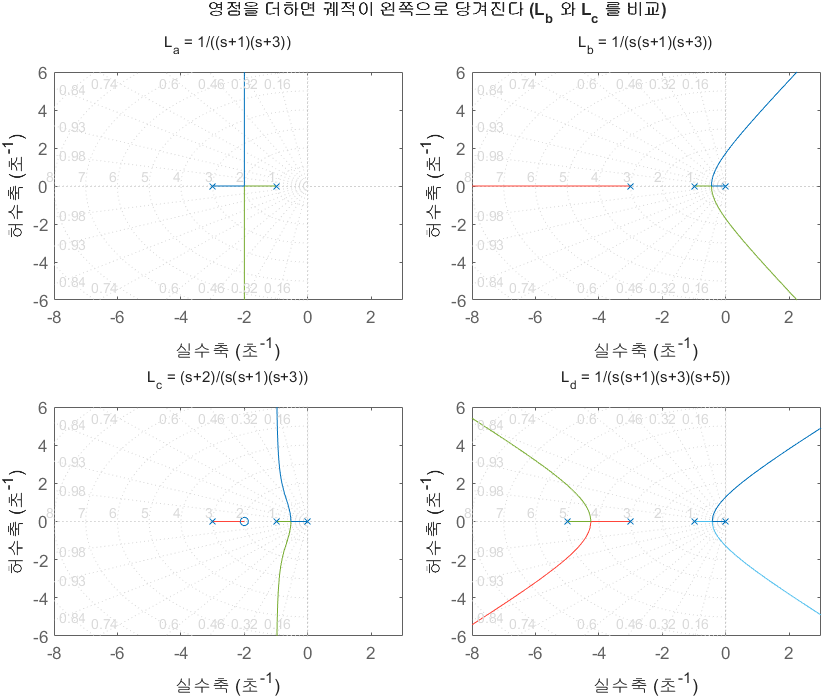

영점을 더하면 궤적이 왼쪽으로 당겨진다

**그림 파일** `w06_four_loci.png` — `make_figures.m` 의 `fig_four_loci` · 다시 만들려면 `make_figures('w06_four_loci')`

**만드는 곳** — `make_figures.m` 의 `fig_four_loci` **직접 바꿔 보려면** — `W06_01_rlocus_rules.m` 의 **5절**에서 영점을 $-2$ 대신 $-0.5$ 로 옮기면 당기는 힘이 더 세집니다

그림 해석 — $L_b$** 와 **$L_c$** 두 칸만 비교하면 됩니다**

$L_b$** 에서 **$L_c$** 로 가는 것이 7주차의 PD 제어입니다.** 영점 하나를 적당한 자리에 놓아 궤적을 통째로 왼쪽으로 끌어옵니다.

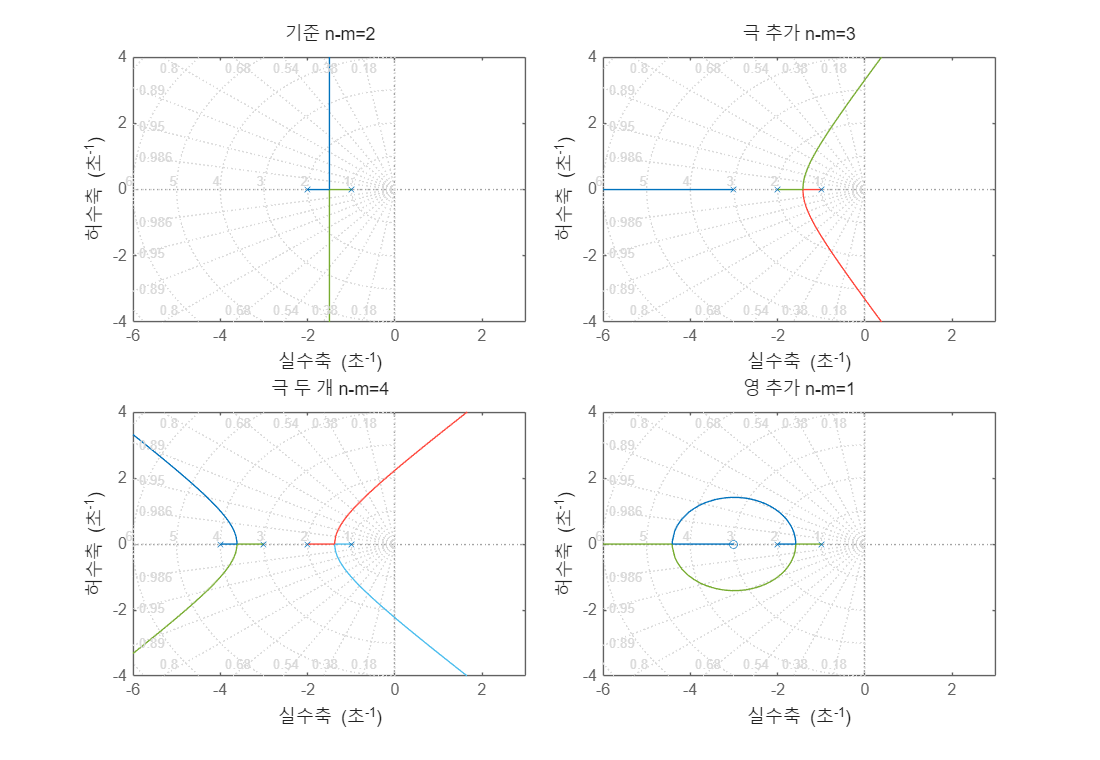

Gb = 1/((s+1)*(s+2));
tiledlayout(2,2,'TileSpacing','compact')
cs = {'기준 n-m=2', Gb; '극 추가 n-m=3', Gb/(s+3);
      '극 두 개 n-m=4', Gb/((s+3)*(s+4)); '영 추가 n-m=1', Gb*(s+3)};
for i=1:4
    nexttile; rlocus(cs{i,2}); grid on; title(cs{i,1});
    xlim([-6 3]); ylim([-4 4]);
end

## 5-1. 그래서 PD 제어가 좋은 것이다

위 그림에서 영점을 추가한 경우를 보십시오. 궤적이 통째로 **왼쪽**으로 옮겨갔습니다.

왼쪽이 좋은 이유는 이미 배웠습니다.

- 왼쪽 $=$ 실수부가 크게 음수 $=$ 빨리 잦아든다 $=$ 정착시간이 짧다

- 허수축에서 멀어졌으므로 불안정해질 걱정도 줄었다

즉 **영점 하나로 더 빠르고 더 안정한** 시스템을 만들 수 있습니다. 그 영점을 만드는 것이 미분제어입니다.


$$C(s) = K_p + K_d s = K_d\left(s + \frac{K_p}{K_d}\right)$$


괄호 안의 $\left(s + K_p/K_d\right)$ 가 추가되는 영점이고, 그 위치는 $K_p/K_d$ 로 **우리가 정할 수 있습니다.** 7주차에서 이 위치를 어떻게 고르는지 배웁니다.

실제로 확인해 보면

- P 제어 — $K = 120.4$ 에서 불안정해진다

- PD 제어 (영점 $s=-3$) — $K = 5000$ 까지 키워도 안정하다

## 6. `sgrid` — 사양 영역을 겹쳐 그리기

4주차에서 그린 사양 영역을 근궤적 위에 얹습니다. 먼저 4주차 그림을 다시 떠올려 봅니다. 초록색이 "합격" 구역이었습니다.

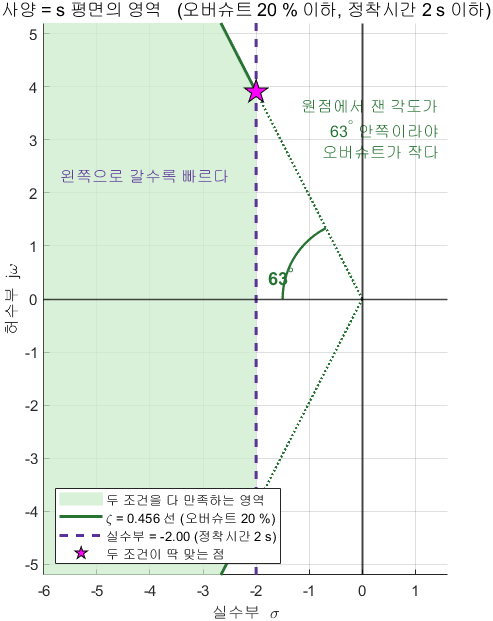

사양의 합격 영역 (오버슈트 20 %, 정착시간 2 s)

**그림 파일** `region_20_2.png` — `common/dg_region.m` 의 `dg_region` · 다시 만들려면 `make_figures('region_20_2')`

**만드는 곳** — `common/dg_region.m` 을 `dg_region(20, 2)` 로 부릅니다 **직접 바꿔 보려면** — 명령창에 `dg_region(5, 1)` 처럼 사양을 바꿔 부르면 영역이 얼마나 좁아지는지 바로 보입니다

그림 해석

이 그림은 아직 **궤적이 없습니다.** 다음 절에서 이 위에 궤적을 얹습니다. 그러면 "이 영역 안에 도달할 수 있는가" 를 눈으로 볼 수 있습니다.

## 6-0. 이 영역을 궤적 위에 얹는 명령이 sgrid

- **하는 일** — $s$ 평면에 등감쇠비 직선과 등고유진동수 원을 그린다

- **입력** — `sgrid(zeta, wn)`. 벡터로 여러 개 가능

- **출력** — 없음. 현재 그림 위에 덧그린다

쓰는 법

- `sgrid` — 기본 격자를 촘촘히

- `sgrid(zeta, wn)` — 지정한 값에만. **설계할 때 이렇게 씁니다**

- `sgrid([], wn)` — 원만

- `sgrid(zeta, [])` — 직선만

**주의** — `sgrid` 는 반드시 `rlocus` **다음에** 부를 것. 먼저 부르면 `rlocus` 가 축을 다시 잡으면서 격자가 지워질 수 있습니다.

4주차와의 대응

- 등감쇠비 직선 $=$ 오버슈트 조건

- 등고유진동수 원 $=$ 정착시간 조건 (4주차의 수직선보다 보수적)

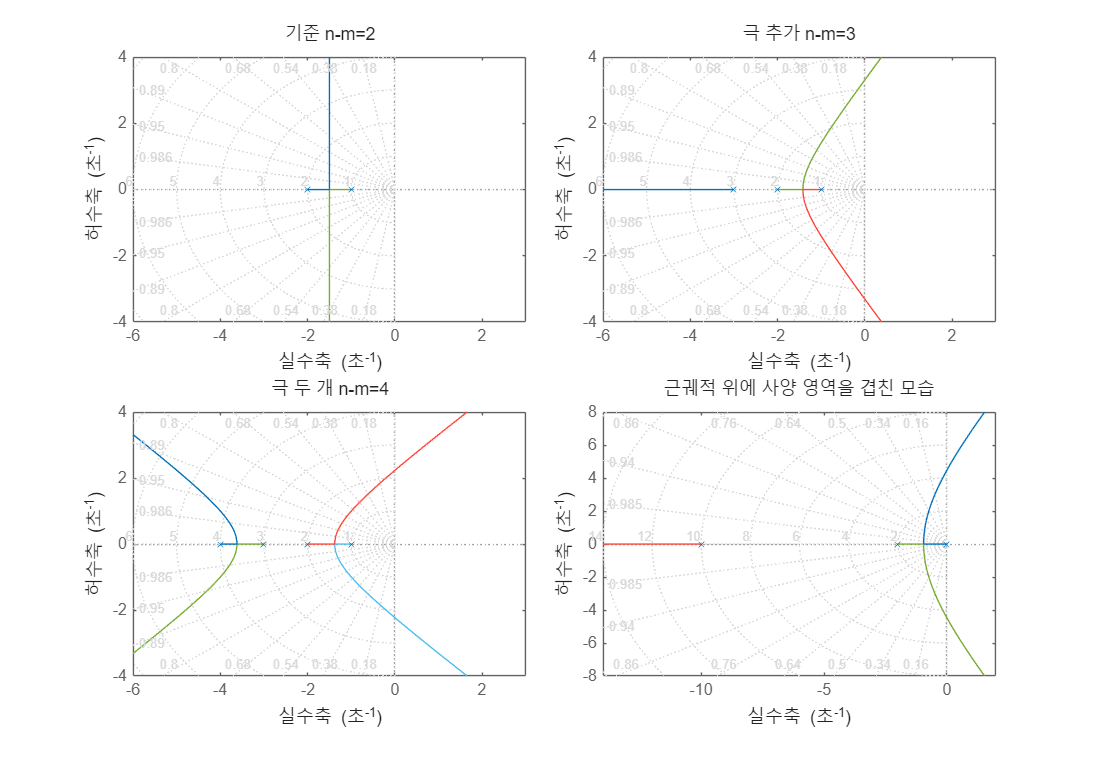

[zm, wm] = spec2pole(20, 2);
rlocus(Gp); hold on; sgrid(zm, wm); axis([-14 2 -8 8])
title('근궤적 위에 사양 영역을 겹친 모습')

## 7. `rlocfind` — 원하는 지점의 이득 읽기

- **하는 일** — 궤적 위에서 지정한 점에 가장 가까운 곳의 이득을 찾는다

- **입력** — `rlocfind(L)` 은 마우스 클릭, `rlocfind(L, p)` 는 점 지정

- **출력** — `[k, poles]`. $k$ 는 이득, `poles` 는 **그때의 폐루프 극점 전부**

주의 두 가지

- 지정한 점이 궤적 위에 없으면 **가장 가까운 점**을 찾아 준다. 그래서 나온 극점이 원하던 위치와 전혀 다를 수 있다. **반드시 확인할 것**

- 반환된 `poles` 는 폐루프 극점 **전부**다. 우리가 볼 것은 보통 지배극점 쌍이다

수업 중에는 인자 없이 불러 마우스로 클릭해 보십시오.

## 8. 설계 절차

앞으로 계속 쓰는 절차입니다.

# 사양을 $\zeta$, $\omega_n$ 으로 바꾼다 — `spec2pole` # 근궤적을 그린다 — `rlocus` # 사양 영역을 겹친다 — `sgrid` # 궤적이 영역을 지나는 지점의 이득을 읽는다 — `rlocfind` # `stepinfo` 로 실제 성능을 확인한다 — **절대 생략 금지** # 제어입력이 실현 가능한지 확인한다 — **자주 잊는 단계**

5번과 6번을 강조하는 이유가 있습니다. 다음 두 절에서 봅니다.

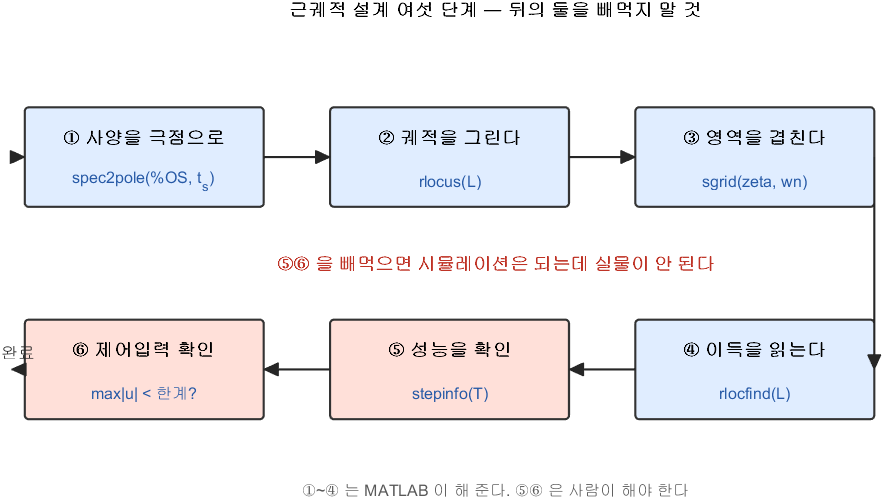

여섯 단계 — 앞의 넷은 MATLAB, 뒤의 둘은 사람

**그림 파일** `w06_design_steps.png` — `common/dg_design_steps.m` 의 `dg_design_steps` · 다시 만들려면 `make_figures('w06_design_steps')`

**만드는 곳** — `common/dg_design_steps.m` (`make_figures('w06_design_steps')`) **직접 밟아 보려면** — `W06_02_design_by_rlocus.m` 이 이 여섯 칸을 절 번호 그대로 따라갑니다

그림 해석

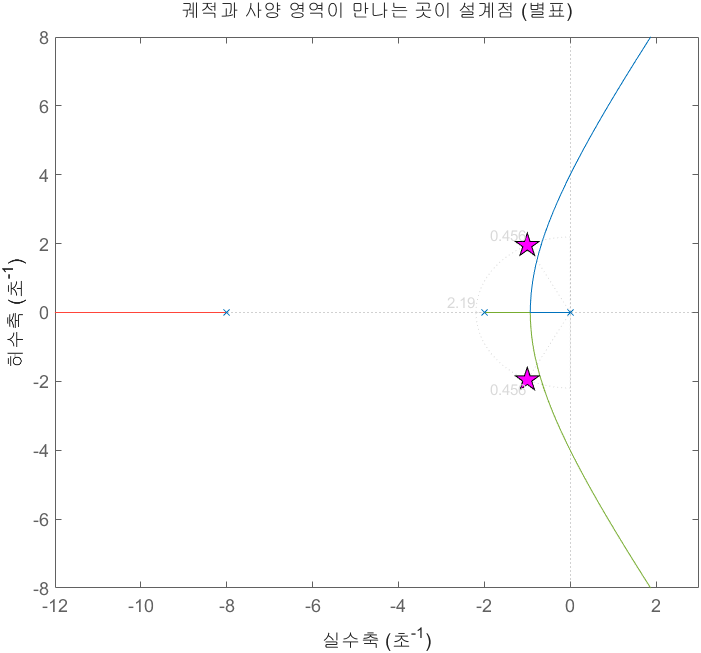

궤적과 사양 영역이 만나는 곳이 설계점

**그림 파일** `w06_sgrid.png` — `make_figures.m` 의 `fig_sgrid` · 다시 만들려면 `make_figures('w06_sgrid')`

**만드는 곳** — `make_figures.m` 의 `fig_sgrid` **직접 바꿔 보려면** — `W06_02_design_by_rlocus.m` 에서 사양을 `spec2pole(10, 1)` 처럼 빡빡하게 바꿔 실행

그림 해석

## 9. 설계가 실패하는 경우 — 궤적이 영역을 지나지 않는다

실습에서 이런 문제를 풀어 봅니다.

- 오버슈트 $20\%$ 이하, 정착시간 $2$ 초 이하

`spec2pole` 이 준 목표 극점은 $-2.0 \pm 3.9j$ 입니다. 그런데 `rlocfind` 로 찾으면 $-0.29 \pm 3.64j$ 가 나옵니다. 전혀 다른 곳입니다.

**원인** — 궤적이 목표점 근처를 지나지 않기 때문입니다.

이 시스템의 궤적을 보면

- 원점 극점과 $s=-2$ 극점이 서로 다가와 만난 뒤

- 복소수가 되어 **위로 곧장 올라간다**

- 올라가는 동안 실수부가 거의 변하지 않는다

즉 아무리 $K$ 를 키워도 극점을 **왼쪽으로 보낼 수가 없습니다.** 정착시간은 실수부가 정하므로 이 사양은 비례제어로 **불가능**합니다.

**근궤적은 **$K$** 로 정해지는 정해진 길입니다.** 그 길이 사양 영역을 지나지 않으면 방법이 없습니다. 그때는 **길 자체를 바꿔야** 하고, 그것이 극이나 영을 추가하는 일입니다. 7주차의 주제가 바로 이것입니다.

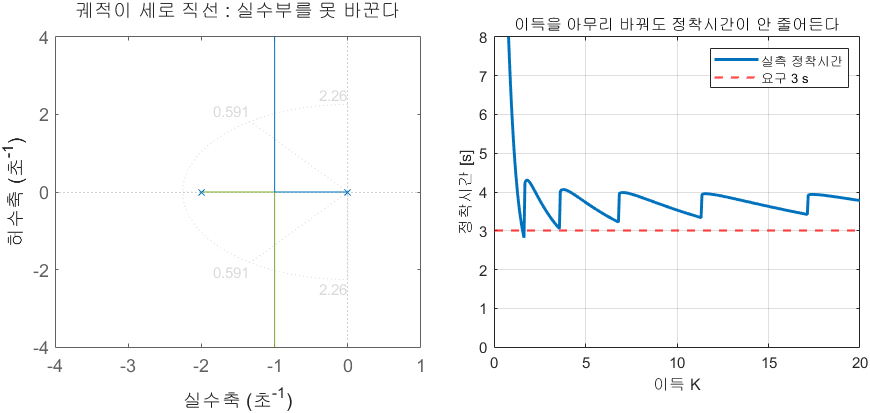

궤적이 세로 직선이면 정착시간을 못 바꾼다

**그림 파일** `w06_design_fail.png` — `make_figures.m` 의 `fig_design_fail` · 다시 만들려면 `make_figures('w06_design_fail')`

**만드는 곳** — `make_figures.m` 의 `fig_design_fail` **직접 확인해 보려면** — `W06_02_design_by_rlocus.m` 의 **5절**이 같은 결론을 `stepinfo` 로 확인합니다

그림 해석

**왼쪽 그림의 세로선 하나가 오른쪽 그림 전체를 설명합니다.** 정착시간은 실수부가 정하는데 그 실수부가 $-1$ 에 고정되어 있으니, $K$ 를 어떻게 해도 정착시간이 안 줄어드는 것입니다.

## 10. 또 하나의 함정 — 포화

근궤적은 **선형 이론**입니다. 포화를 모릅니다.

실제 모터 드라이버가 낼 수 있는 전압에는 한계가 있습니다. 흔히 $12\,\mathrm{V}$, $24\,\mathrm{V}$, $48\,\mathrm{V}$ 를 씁니다.

실습에서 $K = 31.3$ 을 골랐을 때 필요한 최대 전압이 $31.3\,\mathrm{V}$ 였습니다. 구동기별로 결과를 보면

- 포화 없음 — 오버슈트 $39.8\%$, 정착시간 $5.82\,\mathrm{s}$ (선형 예측과 일치)

- $48\,\mathrm{V}$ — 똑같다. 한계에 닿지 않았으므로

- $24\,\mathrm{V}$ — 오버슈트 $37.5\%$. 조금 달라진다

- $12\,\mathrm{V}$ — 오버슈트 $25\%$, 응답이 느려진다

**왜 느려지는가** — 제어기는 "이만큼 주라" 고 명령하는데 구동기가 못 냅니다. 실제로 들어가는 힘이 작아져 응답이 느려집니다.

이 시스템에서는 초기 오차가 $1\,\mathrm{rad}$ 이므로 초기 제어입력이 거의 $K$ 그 자체입니다. 즉 $K$** 가 곧 필요 전압**이라고 봐도 됩니다.

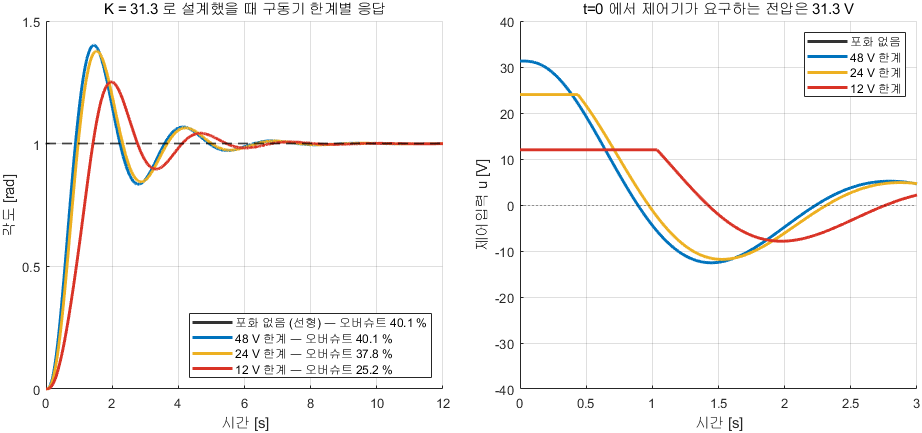

구동기 한계가 응답을 바꾼다

**그림 파일** `w06_saturation.png` — `make_figures.m` 의 `fig_w06_saturation` · 다시 만들려면 `make_figures('w06_saturation')`

**만드는 곳** — `make_figures.m` 의 `fig_w06_saturation` **직접 바꿔 보려면** — `W06_03_run_simulink.m` 의 **2절**에서 `lim` 목록에 $6$ V 를 추가해 보십시오. 더 심하게 느려집니다

그림 해석

여기서 배울 것 — **오버슈트가 줄어든 것만 보고 판단하면 안 됩니다.** 설계한 대로 안 움직인 것이고, 조건이 조금만 달라지면 어떻게 될지 모릅니다. 11주차의 와인드업은 여기서 한 걸음 더 나간 문제입니다.

## 11. 오늘의 정리

- 근궤적은 $1+KL(s)=0$ 의 근이 $K$ 에 따라 움직이는 자취다. 그 식은 폐루프 전달함수의 **분모**이므로 새로운 이론이 아니다

- **각도 조건** $\angle L(s) = \pm 180^\circ(2q+1)$ 이 그 점이 궤적 위인지 정하고, **크기 조건**이 그때의 $K$ 를 정한다. 나머지 규칙은 전부 여기서 나온다

- 실축 위에서는 **오른쪽에 있는 극·영의 개수가 홀수인 구간**이 궤적이다

- 실축을 떠나는 **이탈점**은 $K(\sigma) = -1/L(\sigma)$ 의 봉우리다

- 허수축 교차는 특성방정식에 $s = j\omega$ 를 넣어 실수부·허수부를 각각 $0$ 으로 두면 나온다. 그 $K$ 가 **임계 이득**이고 5주차 라우스 표의 답과 같다

- `rlocus(L)` 로 그린다. $L$ 은 개루프, $K$ 는 빼고 넣는다

- 궤적은 개루프 극점에서 출발해 영점에서 끝난다. 남는 가지는 무한대로

- $n-m$ 이 클수록 오른쪽으로 휘어 불안정해지기 쉽다

- **극을 추가하면 오른쪽으로, 영을 추가하면 왼쪽으로** 궤적이 움직인다

- `sgrid` 로 사양 영역을 겹치고 `rlocfind` 로 이득을 읽는다

- `rlocus` 의 이득 눈금은 성기다. 정확한 값은 따로 계산할 것

- `rlocus` 그림 위에 `legend` 를 부르면 오류가 난다

- **궤적이 사양 영역을 지나지 않으면 비례제어로는 불가능하다**

- 근궤적은 포화를 모른다. 제어입력을 반드시 확인할 것

## 12. 다음 주 예고

오늘 비례제어의 한계를 봤습니다. 궤적이 정해져 있어 그 길 위에만 극점을 놓을 수 있고, 길이 사양 영역을 비껴가면 방법이 없었습니다.

7주차에서는 **길 자체를 바꿉니다.**

- **PD 제어** — 영점을 추가해 궤적을 왼쪽으로 당긴다

- **PI 제어** — 원점에 극점을 추가해 정상상태 오차를 없앤다

- **Lead 보상기** — PD 의 고주파 문제를 고친 실용 버전

- **Lag 보상기** — PI 의 느린 응답 문제를 고친 실용 버전

그리고 `controlSystemDesigner` 앱으로 이 모든 것을 마우스로 해 봅니다.